# INTERPOLACJA

## WPŁYW ROZKŁADU I ILOŚCI PUNKTÓW W DANYCH WEJŚCIOWYCH NA JAKOŚĆ INTERPOLACJI

W tym ćwiczeniu będziemy sprawdzać poprawność przedstawionego przez nas wywodu oraz poznamy praktycznie implikacje z przeprowadzonej analizy. 

Równanie opisujące **błąd interpolacji pomiędzy węzłami** wygląda następująco:

Żeby zbadać jego prawdziwość zrobimy następujące założenia:

1. Biorąc pod uwagę że iloraz różnicowy jest przybliżeniem pochodnej będziemy do rysowania przyjmować iloraz różnicowy uzyskany z interpolacji wielomianem Newtona o najwyższym stopniu.

To nie będzie zatem maksymalny błąd - ale będzie to błąd dla punktu leżącego blisko prawego krańca przedziału interpolacji. Ponieważ zastosujemy równomierne rozłożenie węzłów to właśnie w tej okolicy spodziewamy się największych błędów wraz z dodawaniem kolejnych punktów.

2. Będziemy wyrysowywać 4 wykresy:

- standardowy wykres efektu interpolacji

- wykres opisujący czerwoną część wzoru (opierając się na fakcie, że znamy funkcję oryginalną i umiemy policzyć jej pochodną)

- wykres błędu maksymalnego w całym zakresie interpolacji w funkcji ilości węzłów

- wykres wielkości ilorazu różnicowego obliczonego na prawym krańcu przedziału interpolacji w funkcji ilości węzłów

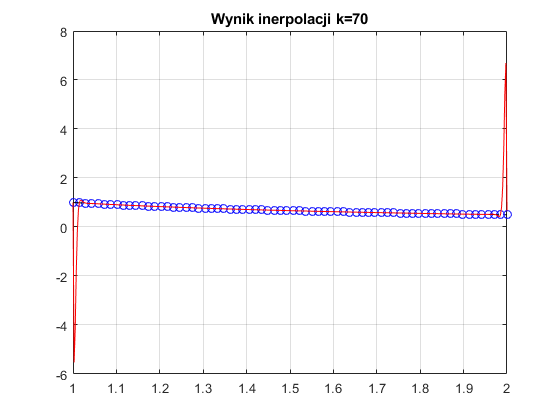

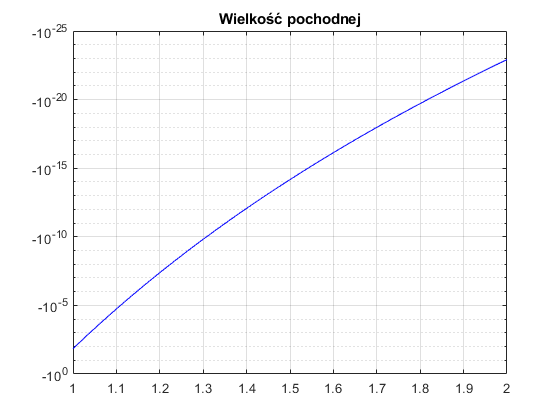

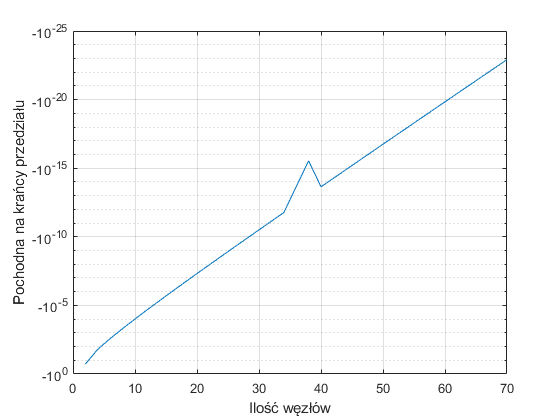

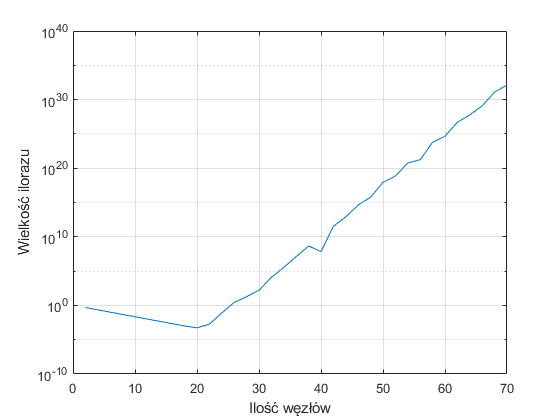

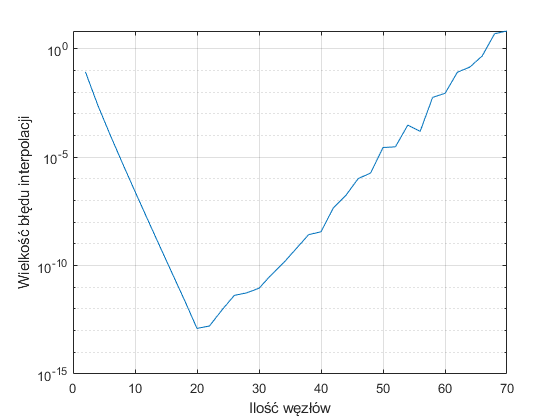

clear all;
close all;

% Tutaj wybieramy nasz przedział interpolacji i funkcję oryginalną
a=1;
b=2;
f=@(x) 1./x;

% Wykorzystamy Symbolic Toolbox do obliczania kolejnych pochodnych funkcji
syms ix
fsyms = 1/ix;

%% Parametry potrzebne do rysowania
xx=linspace(a,b,401);
yy=f(xx);

diff_f = diff(fsyms,3);

ind=1;diff_max=[];index=[];blad_interp=[];diff_end=[];
for i=[2 4 6 8 10 12 14 16 18 20 22 24 26 28 30 32 34 38 40 42 44 46 48 50 52 54 56 58 60 62 64 66 68 70];
   x=linspace(a,b,i);
   y=f(x);
   [xxx, yyy, difff] = NewtonInterpol(x,y,xx);
   diff_max = [diff_max difff];
   figure(1);
   plot(x,y,'ob',xx,yy,'k--',xxx,yyy,'r');grid on;title("Wynik interpolacji k=" + num2str(i));
   blad_interp=[blad_interp max(abs(yy-yyy))];
    
   figure(2);ix=x;
   semilogy(x,abs(subs(diff_f)/prod([1:1:i])),'b');grid on;title("Wielkość pochodnej");
   ix=x(end);
   diff_end = [diff_end (subs(diff_f)/prod([1:1:i]))];
   diff_f = diff(fsyms,i+1);

   figure(3)
   index=[index i];
   semilogy(index, diff_end);grid on;xlabel("Ilość węzłów"); ylabel("Pochodna na krańcy przedziału");
   
   figure(4)
   semilogy(index, abs(diff_max));grid on; xlabel("Ilość węzłów"); ylabel("Wielkość ilorazu");
   
   figure(5)
   semilogy(index, blad_interp);grid on;xlabel("Ilość węzłów"); ylabel("Wielkość błędu interpolacji");
   pause(1);
    
end

Zwróć uwagę, że początkowo wraz ze wzrostem ilości węzłów błąd interpolacji maleje. Jest to spowodowane zarówno faktem, że iloraz różnicowy maleje, jak i faktem, że nasza funkcja nie ma szybko rosnącej wartości pochodnej w przedziale [a,b].

Jednak w pewnym momencie (dla k=20) wartość ilorazu zaczyna szybko narastać. Nieco wolniej narasta błąd (ponieważ pochodna funkcji dalej maleje, ale wolniej niż wzrost ilorazu). Od tego momentu dalsze dokładanie węzłów powoduje ogólny wzrost błędu (w szególności na krańcach przedziału).

**ĆWICZENIE**

**1. Wartość pochodnej oraz wartość ilorazu różnicowego zależy od przedziału [a,b]. Spróbuj znaleźć taki przedział, aby uzyskać najgorszy możliwy efekt - szybko rosnącą pochodną. Zaobserwuj jak zachowa się błąd.**

**2. Spróbuj znaleźć taką funkcję i przedział, aby uzyskać bardzo silny i szybki wzrost błędu.**

Zwróć uwagę na następujące faktu:

- w małym zakresie ilości węzłów - kilku kilkunastu prawie zawsze obserwujemy poprawę błędu

- niezależnie od funkcji zawsze będzie jakaś ilość węzłów dla której błąd ma wartość minimalną i dalej już będzie rósł - jest to cecha każdej interpolacji wielomianowej

Na koniec porównajmy sobie taką samą interpolację, ale zrobioną z rozkładem węzłów zoptymalizowanym wg Czebyszewa. Dla rozkładu równomiernego optymalna ilość węzłów wynosiła k=20 w podstawowym przykładzie. Zwróć uwagę na poziom błędu i wartość optymalną w przypadku rozkładu Czebyszewa:

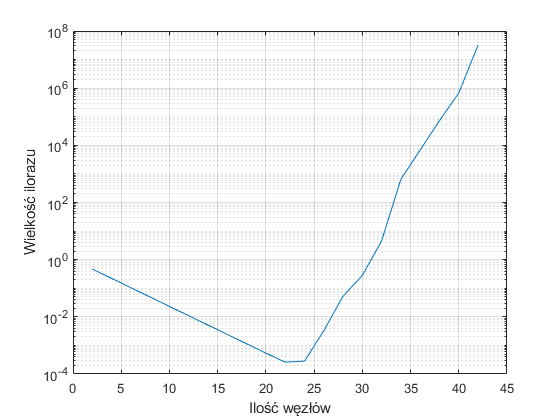

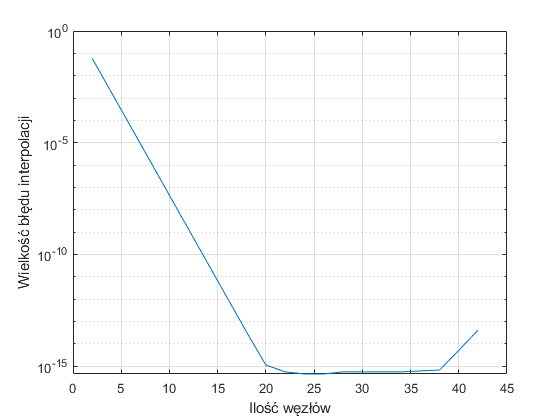

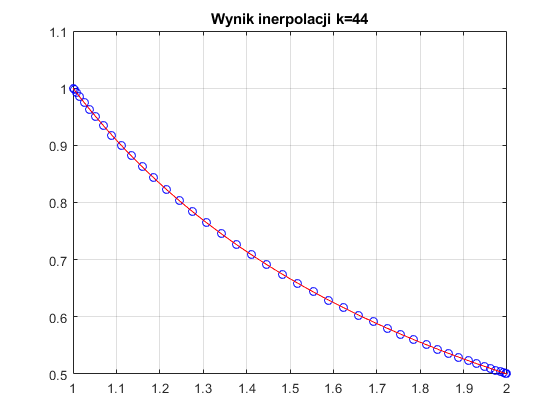

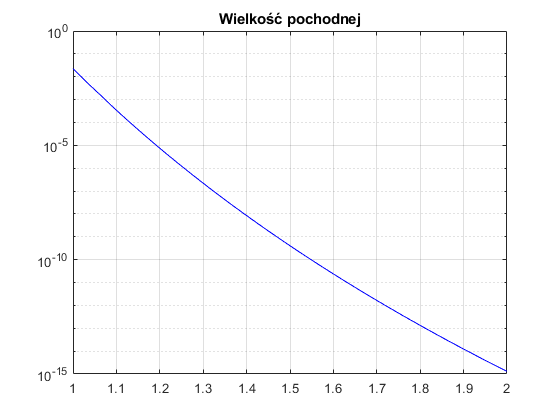

% Tutaj wybieramy nasz przedział interpolacji i funkcję oryginalną
a=1;
b=2;
f=@(x) 1./x;

% Wykorzystamy Symbolic Toolbox do obliczania kolejnych pochodnych funkcji
syms ix
fsyms = 1/ix;

%% Parametry potrzebne do rysowania
xx=linspace(a,b,401);
yy=f(xx);

diff_f = diff(fsyms,3);

ind=1;diff_max=[];index=[];blad_interp=[];
for i=[2 4 6 8 10 12 14 16 18 20 22 24 26 28 30 32 34 38 40 42 44 46 48 50 52 54 56 58 60 62 64 66 68 70];
   k=[0:1:i-1];
   x = 0.5*(a+b)+0.5.*(b-a).*cos((2.*k+1)*pi/(2*numel(k))); % węzły Czebyszewa
   y=f(x);
   [xxx, yyy, difff] = NewtonInterpol(x,y,xx);
   diff_max = [diff_max difff];
   figure(1);
   plot(x,y,'ob',xx,yy,'k--',xxx,yyy,'r');grid on;title("Wynik interpolacji k=" + num2str(i));
   blad_interp=[blad_interp max(abs(yy-yyy))];
    
   figure(2);ix=x;
   semilogy(x,abs(subs(diff_f)/prod([1:1:i])),'b');grid on;title("Wielkość pochodnej");
   diff_f = diff(fsyms,i+1);

   figure(3)
   index=[index i];
   semilogy(index, abs(diff_max));grid on; xlabel("Ilość węzłów"); ylabel("Wielkość ilorazu");
   
   figure(4)
   semilogy(index, blad_interp);grid on;xlabel("Ilość węzłów"); ylabel("Wielkość błędu interpolacji");
   pause(1);
    
end

Zwróć uwagę na:

1. Poziom błędu dla danej ilości węzłów - jest o kilka rzędów wielkości lepszy niż dla rozkładu równomiernego, a także maleje do poziomów mniejszych niż *eps* (rzędu 1e-15).

2. Mimo wszystko jest to dalej interpolacja wielomianowa więc w którymś momencie błąd zacznie narastać, ale porównywalne poziomy błędu jak dla najlepszej interpolacji z węzłami równomiernymi uzyskamy przy dużo większej ilości węzłów.

3. Zatem, żeby uzyskać wystarczającą, albo bardzo dobrą dokładność nie trzeba zawsze robić interpolacji w oparciu o cały zestaw węzłów. Można wybrać te, które leżą możliwie blisko położenia węzłów Czebyszewa - powinniśmy uzyskać lepszą dokładność, szczególnie przy dużym zbiorze punktów przy małym nakładzie obliczeniowym

**WYKROZYSTYWANE FUNKCJE**

function [x,sum, difff] =  NewtonInterpol(xx,f,xxx)
    xStart = xx(1);
    xEnd = xx(end);
    x = xxx;
    n = length(xx);
    d=zeros(n);
    for k = 1 : n - 1
        d(k, 1) = (f(k+1) - f(k))/(xx(k+1) - xx(k));
    end
    for j = 2 : n - 1
        for k = 1 : n - j
            d(k, j) = (d(k+1, j - 1) - d(k, j - 1))/(xx(k+j) - xx(k));
        end
    end
    d=[xx' f' d];
    p1=d(1,2);
    s=1;
    for i=2:n
        s=s.*(x-xx(i-1));
        p1=p1+d(1,i+1).*s;
    end
    sum=p1;
    difff=d(1,end-1);
end
